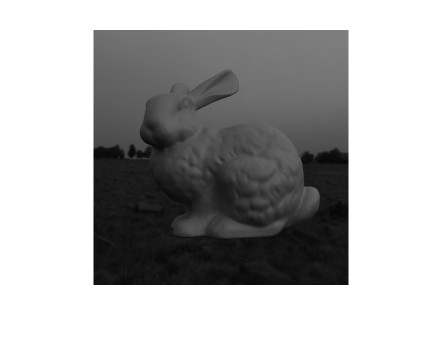

%folder
imageFolder = 'imagemitsuba/';
% 画像フォルダ内の.matファイルを取得
imageFiles = dir(fullfile(imageFolder, '*.mat')); % フォーマットに応じて変更

% 画像ファイルの数を取得
numImages = 12;
images = cell(1, numImages);

figure;

imgcnt = 7;

% filePath
matFilePath = fullfile(imageFolder, imageFiles(imgcnt).name);
data = load(matFilePath);
image_np = data.image_np; 

Ychan = image_np(:,:,2);
% ReinhardTMO
LDR = ReinhardTMO(Ychan);

xyzImg = LDR; 
imshow(xyzImg);

%{
rgbImg = xyz2rgb(xyzImg);
images{imgcnt} = rgbImg;

subplot(1, 1, 1); 
imshow(images{imgcnt});
%}